## BECS4 Optimization Methods Final Project

#### Introduction

The detection and classification of handwritten digits is a very common task for the introduction to neural networks. For this project we use a prewritten neural network workflow from [Rodrigo Sánchez Molina](https://github.com/rsanchezm98) which is based on the coursery course on deep learning. 

The mnist data on handwritten digits is already preprocessed and ready to use.

Github:[https://github.com/rsanchezm98/neural-network-from-scratch.git](https://github.com/rsanchezm98/neural-network-from-scratch.git)

### NN-Architecture

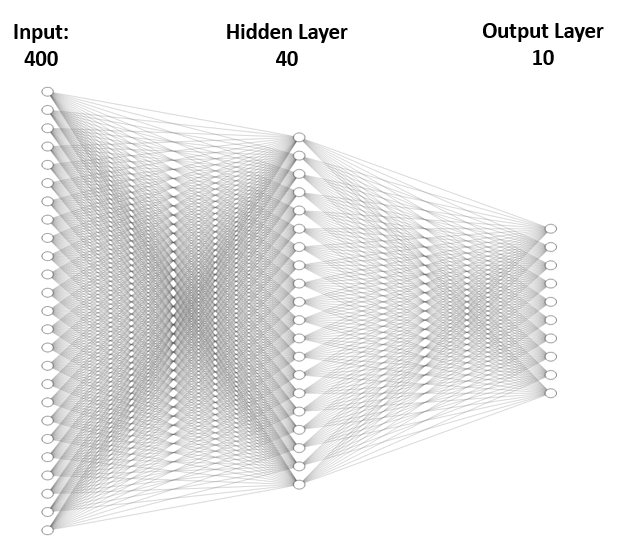

#### Input digits (20X20)

#### Project goal:

The goal of the project is to evaluate different optimization methods to find the optimal weights in the neural network. The methods used are:

- Gradient descent

- Mini-batch gradient descent

- Stochastic gradient descent

- Adagrad.

- Adadelta.

- RMSprop.

- Adam.

#### Data visualization

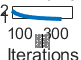

Iteration #: 25 / 1000 | Cost J: 2.6735 | Precission: 67.92
Iteration #: 50 / 1000 | Cost J: 1.824 | Precission: 78.5
Iteration #: 75 / 1000 | Cost J: 1.4075 | Precission: 84.14
Iteration #: 100 / 1000 | Cost J: 1.1611 | Precission: 87.06
Iteration #: 125 / 1000 | Cost J: 1.0086 | Precission: 88.92
Iteration #: 150 / 1000 | Cost J: 0.90698 | Precission: 89.48
Iteration #: 175 / 1000 | Cost J: 0.83559 | Precission: 90.16
Iteration #: 200 / 1000 | Cost J: 0.78305 | Precission: 90.64
Iteration #: 225 / 1000 | Cost J: 0.74268 | Precission: 91
Iteration #: 250 / 1000 | Cost J: 0.71046 | Precission: 91.34
Iteration #: 275 / 1000 | Cost J: 0.68396 | Precission: 91.66
Iteration #: 300 / 1000 | Cost J: 0.66161 | Precission: 92.06
Iteration #: 325 / 1000 | Cost J: 0.64237 | Precission: 92.42
Iteration #: 350 / 1000 | Cost J: 0.62554 | Precission: 92.5


rng(0); % seed for the random number generator
cd 'C:\Users\kevin yar\Desktop\neural_network_mnist\neural_network_mninst'
disp('Loading data...')

% load train data
train_data = load('mnist_train.csv');

labels = train_data(:,1);
y = zeros(10,length(train_data)); % output labels for training
for i = 1:length(train_data)
    y(labels(i)+1,i) = 1;
end

% preprocessing
images = train_data(:,2:785);
images = images/255;
images = images'; % Input vectors for training

% load test data
test_data = load('mnist_test.csv');
test_labels = test_data(:,1);
test_y = zeros(10,10000);
for i = 1:length(test_data)
    test_y(test_labels(i)+1,i) = 1;
end

% preproessing
test_images = test_data(:,2:785);
test_images = test_images/255;
test_images = test_images';


size_hl1 = 100; % Number of neurons in the first hidden layer
size_hl2 = 50; % Number of neurons in the second hidden layer


% Construct model with specifed optimizer for training
lr = 0.001; % learning rate
model = NN(size_hl1, size_hl2, 'Adam', lr);

% Alternatively with SGD optimizer
% lr = 0.1;
% model = NN(hn1, hn2, 'SGD', lr);

epochs = 10; % Number of training epochs

batch_size = 100; % Mini-batch size

disp('Starting epoch 1');
disp(' ');

% Epoch loop
for e = 1:epochs 
    
    samples = 1;
    
    % Loop over gradient descent steps
    for j = 1:length(train_data)/batch_size 
        
        for i = samples:samples+batch_size-1 % Loop over each minibatch

            % Calculate gradients with backpropagation
            model = model.backpropagate(images(:,i), y(:,i));
            
        end
    
        % Gradient descent (optimizer step)
        model = model.step();
          
        % Number of data points covered (+1)
        samples = samples + batch_size;
    
    end
    
    fprintf('Epochs:');
    disp(e) % Track number of epochs
    
    
    % Evaluate model accuracy
    disp('Evaluating model')
    hits = 0;
    n = length(test_data);
    for i = 1:n

        out = model.predict(test_images(:,i)); % model prediction vector
        [~, num] = max(out); % Find highest prediction score

        if test_labels(i) == (num-1)
            hits = hits + 1; % Count the number of correct classifications
        end

    end
    fprintf('Accuracy: ');
    fprintf('%f',hits/n*100);
    disp(' %');
    disp(' ');
    
    
    [images,y] = shuffle(images,y); % Shuffle order of the images for next epoch
end


disp('Done');



